data_table = readtable("Full_Detumble_History.csv");

thrust_vec = [data_table.U_thrust, data_table.V_thrust, data_table.W_thrust]';
thrust_quat = thrust_vec_to_quat3(thrust_vec, data_table.is_thrusting, [0; 0; 0; 1])

thrust_quat =                          0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0     -2.53974358904729e-17      4.74338450462408e-18      2.79453109958139e-17      1.02999206386123e-17      1.19262238973405e-18     -5.05238212378245e-17      4.64038529823796e-17     -3.18890963982299e-17      3.19229777161201e-17      1.46468937239214e-17      1.01643953670516e-

data_table.thrust_quat_x = thrust_quat(1, :)';
data_table.thrust_quat_y = thrust_quat(2, :)';
data_table.thrust_quat_z = thrust_quat(3, :)';
data_table.thrust_quat_w = thrust_quat(4, :)';

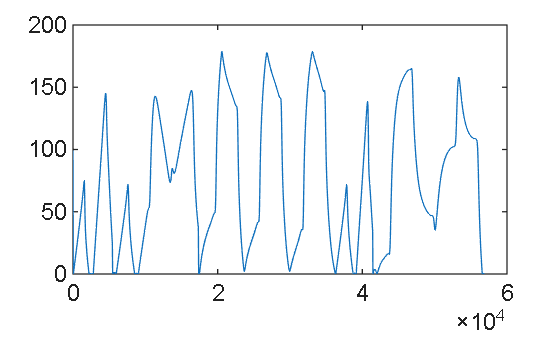

thrust_vec_ck = quat_rot_array(thrust_quat, [ones([1, size(thrust_quat, 2)]); zeros([2, size(thrust_quat, 2)])]);
figure
plot(data_table.Time, acosd(dot(thrust_vec_ck, thrust_vec) ./ (vecnorm(thrust_vec_ck) .* vecnorm(thrust_vec))))

qs = [data_table.q_x'; data_table.q_y'; data_table.q_z'; data_table.q_w'];

angvel_approx = rad2deg(qLog(q_mul_array(q_conj(qs(:, 2:end)), qs(:, 1:end-1)))) ./ diff(data_table.Time)';

angvel_approx_sc = rad2deg(qLog(q_mul_array(q_conj(thrust_quat(:, 2:end)), thrust_quat(:, 1:end-1)))) ./ diff(data_table.Time)';

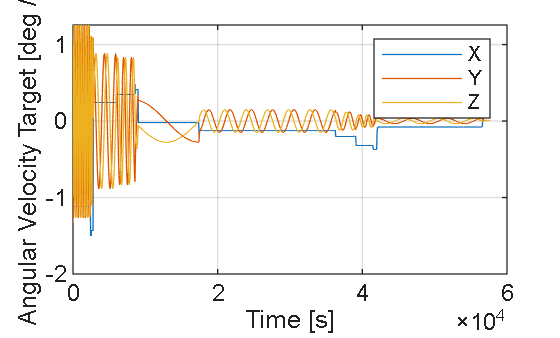

plot(data_table.Time(2:end), angvel_approx)
grid on
xlabel("Time [s]")
ylabel("Angular Velocity Target [deg / s]")
legend("X", "Y", "Z")

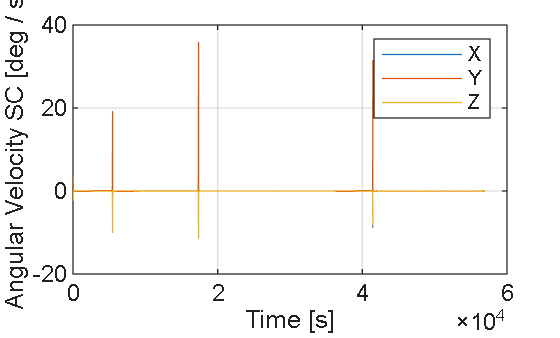

figure
plot(data_table.Time(2:end), angvel_approx_sc)
grid on
xlabel("Time [s]")
ylabel("Angular Velocity SC [deg / s]")
legend("X", "Y", "Z")

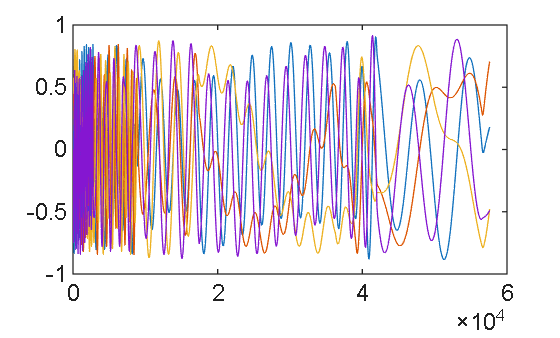

plot(data_table.Time, qs)

writetable(data_table, "Detumble_History_with_thrustquat2.csv")

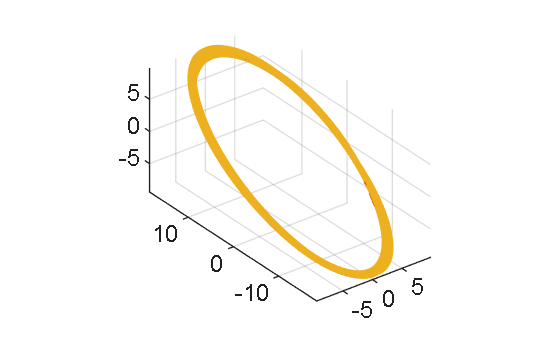

figure
plot3(data_table.chaser_x, data_table.chaser_y, data_table.chaser_z); hold on
quiver3(data_table.chaser_x, data_table.chaser_y, data_table.chaser_z, data_table.U_thrust .* data_table.is_thrusting, data_table.V_thrust .* data_table.is_thrusting, data_table.W_thrust .* data_table.is_thrusting, 5)
quiver3(data_table.chaser_x, data_table.chaser_y, data_table.chaser_z, thrust_vec_ck(1,:)', thrust_vec_ck(2,:)', thrust_vec_ck(3,:)', 5)
axis equal
grid on

function [quat] = thrust_vec_to_quat(T_vec)
    T_vec_normalized = T_vec ./ vecnorm(T_vec);
    angle = acos(T_vec_normalized(1, :));
    %rot_axis = [zeros([1, size(T_vec, 2)]); -T_vec_normalized(3, :); T_vec_normalized(2, :)]; % cross b_x with T_vec
    rot_axis = cross([ones([1, size(T_vec, 2)]); zeros([2, size(T_vec, 2)])], T_vec_normalized); % cross b_x with T_vec
    quat = qExp(angle .* rot_axis);
end

function [quat] = thrust_vec_to_quat2(T_vec)
    T_vec = T_vec ./ vecnorm(T_vec);
    w = 1 + T_vec(1, :);
    xyz = cross([ones([1, size(T_vec, 2)]); zeros([2, size(T_vec, 2)])], T_vec); % cross b_x with T_vec
    quat = [xyz; w];
    quat = quat ./ vecnorm(quat);
end

function [quats] = thrust_vec_to_quat3(T_vec, is_thrusting, q0)
    thrust_i = find(is_thrusting);
    quats = zeros([4, numel(is_thrusting)]);

    prev_i = 1;
    for j = 1 : numel(thrust_i)
        q1 = thrust_vec_to_quat2(T_vec(:, thrust_i(j)));
        N = thrust_i(j) - prev_i;
        quats(:, prev_i + (0:N - 1)) = slerp(q0, q1, N);
        
        prev_i = thrust_i(j);
        q0 = q1;
    end

end

function [quats] = slerp(q0, q1, N)
    error = qLog(q_mul_array(q_conj(q0), q1));
    t = linspace(0, 1, N);
    quats = q_mul_array(repmat(q0, 1, N), qExp(error .* t));
end

function [q] = qExp(tau)
    N = size(tau, 2);
    q = zeros([4, N]);
    for k = 1 : N
        theta = norm(tau(:, k));
        if theta > 1e-10
            u = tau(:, k) / theta;
            q(:, k) = [u * sin(theta / 2); cos(theta / 2)];
        else
            q(:, k) = [0; 0; 0; 1];
        end
    end
end

function [tau] = qLog(q)
    N = size(q, 2);
    for k = 1 : N
        w = q(4, k);
        v = q(1:3, k);
        w = w * sign(w);
        v = v * sign(w);
        tau(:, k) = 2 * v * atan2(norm(v), w) / norm(v);
    end
end